# Signal Processing Framework

## Max Energy Microphone Selection Algorithm 

% Load all 4 mic signals
[file1, path1] = uigetfile('*.wav', 'Select Mic 1'); if isequal(file1, 0), return; end
[Fetalsignal1, fs1] = audioread(fullfile(path1, file1));

[file2, path2] = uigetfile('*.wav', 'Select Mic 2'); if isequal(file2, 0), return; end
[Fetalsignal2, fs2] = audioread(fullfile(path2, file2));

[file3, path3] = uigetfile('*.wav', 'Select Mic 3'); if isequal(file3, 0), return; end
[Fetalsignal3, fs3] = audioread(fullfile(path3, file3));

[file4, path4] = uigetfile('*.wav', 'Select Mic 4'); if isequal(file4, 0), return; end
[Fetalsignal4, fs4] = audioread(fullfile(path4, file4));

% --- Check all sampling rates are the same
if ~isequal(fs1, fs2, fs3, fs4)
    error('All audio files must have the same sampling rate.');
end

% --- Convert stereo to mono if needed
Fetalsignal1 = mean(Fetalsignal1, 2);
Fetalsignal2 = mean(Fetalsignal2, 2);
Fetalsignal3 = mean(Fetalsignal3, 2);
Fetalsignal4 = mean(Fetalsignal4, 2);

% --- Truncate all signals to the same minimum length
minLength = min([length(Fetalsignal1), length(Fetalsignal2), length(Fetalsignal3), length(Fetalsignal4)]);
Fetalsignal1 = Fetalsignal1(1:minLength);
Fetalsignal2 = Fetalsignal2(1:minLength);
Fetalsignal3 = Fetalsignal3(1:minLength);
Fetalsignal4 = Fetalsignal4(1:minLength);

% --- Combine into a matrix: rows = samples, cols = mics
micSignals = [Fetalsignal1, Fetalsignal2, Fetalsignal3, Fetalsignal4];

% --- Calculate energy for each mic
micEnergies = sum(micSignals.^2, 1);

% --- Identify mic with highest energy
[~, bestMicIndex] = max(micEnergies);
% --- Now redefine a seperate variable as that of the highest energy mic
Fetalsignal = micSignals(:, bestMicIndex);
fsFetal = fs1

fsFetal = 32000

% --- Display results
fprintf('Microphone with highest energy: Mic %d\n', bestMicIndex);

Microphone with highest energy: Mic 1


disp('Energies per microphone:');

Energies per microphone:


disp(micEnergies);

   53.2648   53.2648   51.3665   51.3665



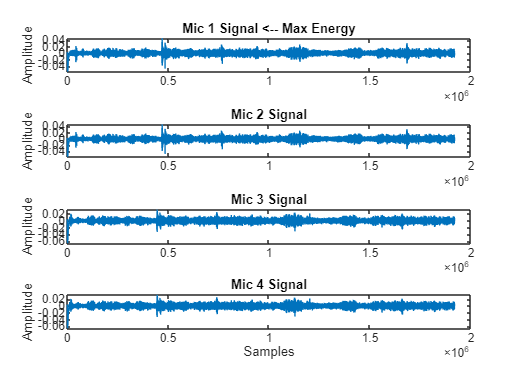


% --- Optional: plot signals and highlight best
figure;
for i = 1:4
    subplot(4,1,i);
    plot(micSignals(:,i));
    if i == bestMicIndex
    title(sprintf('Mic %d Signal <-- Max Energy', i));
    else
    title(sprintf('Mic %d Signal', i));
    end
    ylabel('Amplitude');
end
xlabel('Samples');

## Maternal Heartbeat Signal Selection

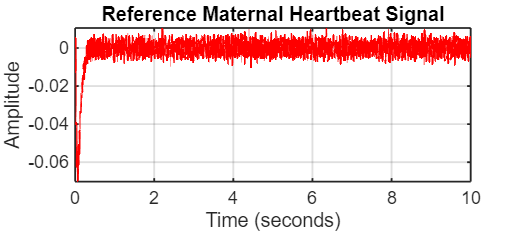

[filenameMaternal, pathnameMaternal] = uigetfile({'*.wav', 'WAV Files (*.wav)'}, 'Select the Maternal Heartbeat WAV File');
if isequal(filenameMaternal, 0)
    disp('User canceled maternal heartbeat file selection.');
    return;
end

filePathMaternal = fullfile(pathnameMaternal, filenameMaternal);
[maternalSignal, fsMaternal] = audioread(filePathMaternal);

% Convert to mono if stereo
if size(maternalSignal, 2) == 2
    maternalSignal = mean(maternalSignal, 2);
end

% Time vector for maternal signal
tMaternal = (0:length(maternalSignal)-1) / fsMaternal;
% Create maternal signal plot
figure('Units','centimeters','Position',[5 5 18 8]);

plot(tMaternal, maternalSignal, 'r', 'LineWidth', 1.5);
xlabel('Time (seconds)', 'FontSize', 14);
ylabel('Amplitude', 'FontSize', 14);
title('Reference Maternal Heartbeat Signal', 'FontSize', 16);
xlim([0, 10]);

grid on;
set(gca, 'FontSize', 12, 'LineWidth', 1.2);
exportgraphics(gcf, 'MaternalSignal_Raw.pdf', 'ContentType', 'vector');

## Fetal Heartbeat Signal Bandpass filter 

% --- Bandpass Filter ---
bpFilt = designfilt('bandpassiir', ...
    'FilterOrder', 6, ...
    'HalfPowerFrequency1', 1, ...
    'HalfPowerFrequency2', 300, ...
    'SampleRate', fsFetal);

filteredSignal = filtfilt(bpFilt, Fetalsignal);
%filteredSignal = Fetalsignal;

% --- Time vector ---
t = (0:length(Fetalsignal)-1) / fsFetal;

% --- Plotting ---
figure('Units','centimeters','Position',[5 5 18 12]); % Bigger figure for LaTeX

tiledlayout(2,1,'Padding','compact','TileSpacing','compact'); % Compact layout

% Define font sizes
titleFont = 16;
labelFont = 14;
axisFont = 12;

% --- Original Signal ---
nexttile
plot(t, Fetalsignal, 'b', 'LineWidth', 1.5);
title('Original Fetal Heartbeat Signal', 'FontSize', titleFont);
xlabel('Time (s)', 'FontSize', labelFont);
ylabel('Amplitude', 'FontSize', labelFont);
xlim([0, 10]);
grid on;
set(gca, 'FontSize', axisFont, 'LineWidth', 1.2);

% --- Filtered Signal ---
nexttile
plot(t, filteredSignal, 'r', 'LineWidth', 1.5);
title('Filtered Fetal Heartbeat Signal (1–300 Hz)', 'FontSize', titleFont);
xlabel('Time (s)', 'FontSize', labelFont);
ylabel('Amplitude', 'FontSize', labelFont);
xlim([0, 10]);
grid on;
set(gca, 'FontSize', axisFont, 'LineWidth', 1.2);

disp('Bandpass filter applied (1–300 Hz).');

Bandpass filter applied (1–300 Hz).


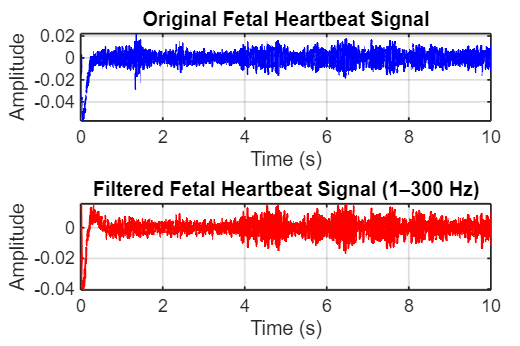



exportgraphics(gcf, 'FetalFilterPlot.pdf', 'ContentType', 'vector');


% Normalize filtered signal before saving (to avoid clipping)
filteredSignalNorm = filteredSignal / max(abs(filteredSignal));

% Save as WAV file
audiowrite('Filtered_Fetal_Heartbeat.wav', filteredSignalNorm, fsFetal);

fprintf('✅ Filtered fetal heartbeat WAV file saved as: Filtered_Fetal_Heartbeat.wav\n');

✅ Filtered fetal heartbeat WAV file saved as: Filtered_Fetal_Heartbeat.wav


## Maternal Heartbeat Signal Bandpass Filter


% --- Bandpass Filter for Maternal Signal ---
maternalBpFilt = designfilt('bandpassiir', ...
    'FilterOrder', 6, ...
    'HalfPowerFrequency1', 1, ...
    'HalfPowerFrequency2', 600, ...
    'SampleRate', fsMaternal);

%maternalFiltered = filtfilt(maternalBpFilt, maternalSignal);
maternalFiltered = maternalSignal;


% --- Time vector ---
tMaternal = (0:length(maternalSignal)-1) / fsMaternal;

% --- Plotting ---
figure('Units','centimeters','Position',[5 5 18 12]); % Larger figure for better LaTeX export

tiledlayout(2,1,'Padding','compact','TileSpacing','compact'); % Better layout

% Font sizes
titleFont = 16;
labelFont = 14;
axisFont = 12;

% --- Original Maternal Signal ---
nexttile
plot(tMaternal, maternalSignal, 'b', 'LineWidth', 1.5);
title('Original Maternal Heartbeat Signal', 'FontSize', titleFont);
xlabel('Time (s)', 'FontSize', labelFont);
ylabel('Amplitude', 'FontSize', labelFont);
xlim([0, 10]);
grid on;
set(gca, 'FontSize', axisFont, 'LineWidth', 1.2);

% --- Filtered Maternal Signal ---
nexttile
plot(tMaternal, maternalFiltered, 'r', 'LineWidth', 1.5);
title('Filtered Maternal Heartbeat Signal (1–600 Hz)', 'FontSize', titleFont);
xlabel('Time (s)', 'FontSize', labelFont);
ylabel('Amplitude', 'FontSize', labelFont);
xlim([0, 10]);
grid on;
set(gca, 'FontSize', axisFont, 'LineWidth', 1.2);

disp('Bandpass filter applied to maternal signal (1–600 Hz).');

Bandpass filter applied to maternal signal (1–600 Hz).


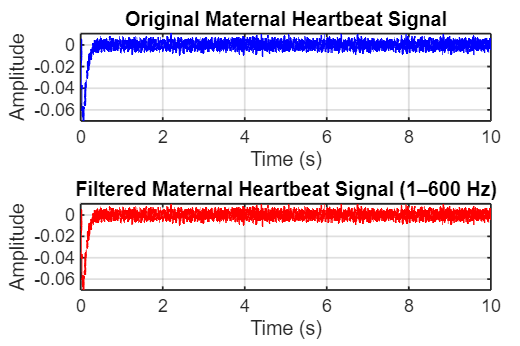

exportgraphics(gcf, 'MaternalFilterPlot.pdf', 'ContentType', 'vector');

## Active Noise Cancellation

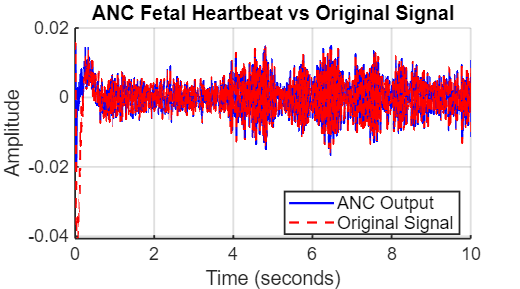

function [x_hat, error, weights] = ANC(signal, stepsize, filter_size, reference)
    samples = length(signal);
    weights = zeros(filter_size, 1);
    x_hat = zeros(1, samples);
    error = zeros(1, samples);

    for n = filter_size:samples
        % Construct predictor input u(n)
        u = reshape(reference(n:-1:n-filter_size+1), [], 1);  % Ensure column vector

        eta_hat = weights' * u;  % Should now be valid

        error(n) = signal(n) - eta_hat;

        weights = weights + stepsize * error(n) * u;

        x_hat(n) = error(n);
    end
end

[ANC_FHB,FHB_error,FHB_weights] = ANC(filteredSignal,0.01,128,maternalFiltered);
t_anc = (0:length(ANC_FHB)-1) / fsFetal;
t = (0:length(filteredSignal)-1) / fsFetal;

figure('Units','centimeters','Position',[5 5 18 10]);  % Proper size for LaTeX export
hold on;

% Plot ANC Output (blue solid)
plot(t_anc, ANC_FHB, 'b', 'LineWidth', 1.5);           
    
% Plot Original Filtered Signal (red dashed)
plot(t, filteredSignal, 'r--', 'LineWidth', 1.5);       

xlabel('Time (seconds)', 'FontSize', 14);
ylabel('Amplitude', 'FontSize', 14);
title('ANC Fetal Heartbeat vs Original Signal', 'FontSize', 16);

% Set common x-axis limits
xlim([0, 10]);

grid on;

% Set legend with increased font size
legend('ANC Output', 'Original Signal', 'Location', 'best', 'FontSize', 12);

% Increase tick label font sizes and axis line width
set(gca, 'FontSize', 12, 'LineWidth', 1.2);

exportgraphics(gcf, 'ANC_vs_Original.png', 'ContentType', 'vector');


% Normalize ANC output to avoid clipping
ANC_FHB_norm = ANC_FHB / max(abs(ANC_FHB));

% Save as WAV
audiowrite('ANC_Output.wav', ANC_FHB_norm, fsFetal);

fprintf('✅ WAV file saved as: ANC_Output.wav\n');

✅ WAV file saved as: ANC_Output.wav


## PCA 

% Parameters
windowSize = 1024;
overlap = 512;

% Use ANC output (denoised signal)
frames = buffer(ANC_FHB, windowSize, overlap, 'nodelay');

Unrecognized function or variable 'ANC_FHB'.


% Normalize columns (zero mean per frame)
frames = frames - mean(frames, 1);

% PCA decomposition
[coeff, score, latent, tsquared, explained] = pca(frames');

% Variance plot
figure;
pareto(explained);
xlabel('Principal Component');
ylabel('Variance Explained (%)');

% Reconstruct using only first principal component
k = 5; % number of PCs to keep
fs = fsFetal;  % from your ANC input

reconstructed = score(:, 1:k) * coeff(:, 1:k)';  % low-dimensional reconstruction
reconstructed = reconstructed';  % reshape to original framing

% Flatten and construct time vector
reconstructedSignal = reconstructed(:);
t = (0:length(reconstructedSignal)-1) / fs;

% Plot the reconstructed waveform
figure('Units','centimeters','Position',[5 5 18 8]);  % Wider for single plot

plot(t, reconstructedSignal, 'b', 'LineWidth', 1.5);
xlabel('Time (seconds)', 'FontSize', 14);
ylabel('Amplitude', 'FontSize', 14);
title('PCA Reconstructed Fetal Heartbeat (After ANC)', 'FontSize', 16);

xlim([8.5, 9]);
grid on;

set(gca, 'FontSize', 12, 'LineWidth', 1.2);

exportgraphics(gcf, 'PCA_Reconstructed_FHB.pdf', 'ContentType', 'vector');

% Normalize and save as WAV file
reconstructedSignalNorm = reconstructedSignal / max(abs(reconstructedSignal));
outputFilename = 'PCA_Reconstructed_FHB.wav';
audiowrite(outputFilename, reconstructedSignalNorm, fs);
disp(['WAV file saved as: ', outputFilename]);


# Comparison 

### Normalised Waveform Comparison

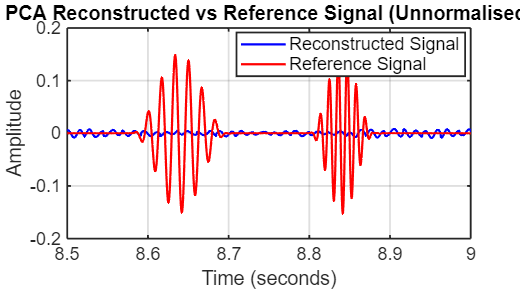

% Load Reference Signal
[filenameref, pathnameref] = uigetfile({'*.wav', 'WAV Files (*.wav)'}, 'Select the Reference Signal');
if isequal(filenameref, 0)
    disp('User canceled reference signal selection.');
    return;
end

filePathref = fullfile(pathnameref, filenameref);
[refSignal_raw, fsRef] = audioread(filePathref);

if size(refSignal_raw, 2) == 2
    refSignal_raw = mean(refSignal_raw, 2);  % Convert to mono
end

% Backup the original reconstructed signal first
reconstructedSignal_raw = reconstructedSignal;

% --- Trim both raw signals to same length
minLen = min(length(reconstructedSignal_raw), length(refSignal_raw));
reconstructedSignal_raw_trimmed = reconstructedSignal_raw(1:minLen);
refSignal_raw_trimmed = refSignal_raw(1:minLen);
t_plot = (0:minLen-1) / fsRef;

% --- Plot 1: UNNORMALISED
figure('Units','centimeters','Position',[5 5 18 10]);
plot(t_plot, reconstructedSignal_raw_trimmed, 'b', 'LineWidth', 1.5, 'DisplayName', 'Reconstructed Signal');
hold on;
plot(t_plot, refSignal_raw_trimmed, 'r', 'LineWidth', 1.5, 'DisplayName', 'Reference Signal');
xlabel('Time (seconds)', 'FontSize', 14);
ylabel('Amplitude', 'FontSize', 14);
title('PCA Reconstructed vs Reference Signal (Unnormalised)', 'FontSize', 16);
xlim([8.5, 9]); grid on;
legend('show', 'FontSize', 12, 'Location', 'best');
set(gca, 'FontSize', 12, 'LineWidth', 1.2);
exportgraphics(gcf, 'PCA_vs_Reference_Unnormalised.pdf', 'ContentType', 'vector');

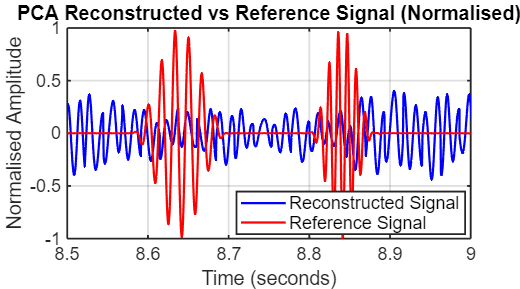


% --- Normalise signals
reconstructedSignal_norm = reconstructedSignal_raw_trimmed / max(abs(reconstructedSignal_raw_trimmed));
refSignal_norm = refSignal_raw_trimmed / max(abs(refSignal_raw_trimmed));

% --- Plot 2: NORMALISED
figure('Units','centimeters','Position',[5 5 18 10]);
plot(t_plot, reconstructedSignal_norm, 'b', 'LineWidth', 1.5, 'DisplayName', 'Reconstructed Signal');
hold on;
plot(t_plot, refSignal_norm, 'r', 'LineWidth', 1.5, 'DisplayName', 'Reference Signal');
xlabel('Time (seconds)', 'FontSize', 14);
ylabel('Normalised Amplitude', 'FontSize', 14);
title('PCA Reconstructed vs Reference Signal (Normalised)', 'FontSize', 16);
xlim([8.5, 9]); grid on;
legend('show', 'FontSize', 12, 'Location', 'best');
set(gca, 'FontSize', 12, 'LineWidth', 1.2);
exportgraphics(gcf, 'PCA_vs_Reference_Normalised.pdf', 'ContentType', 'vector');

## Beat Per Minute Estimator

Reference Signal BPM: Detected 140 beats, estimated BPM: 139.99


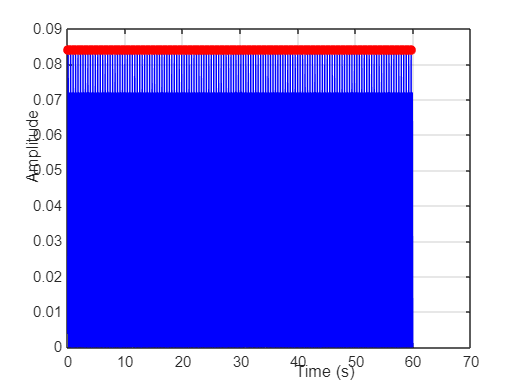

function [bpm, locs, ibi] = estimateBPM(signal, fs, plotTitle)

    if nargin < 3
        plotTitle = 'Signal Envelope and Peak Detection';
    end

    % Step 1: Envelope extraction
    envelope = abs(signal);

    % Step 2: Smoothing (50 ms window)
    window = round(0.05 * fs);
    envelope_smooth = movmean(envelope, window);

    % Step 3: Peak detection parameters
    min_distance = round(0.3 * fs);  % 300 ms apart
    min_height = mean(envelope_smooth);  % Adaptive threshold

    % Step 4: Peak detection
    [~, locs] = findpeaks(envelope_smooth, ...
        'MinPeakDistance', min_distance, ...
        'MinPeakHeight', min_height);

    % Step 5: Time between peaks
    peak_times = locs / fs;
    ibi = diff(peak_times);  % Inter-beat intervals

    % Step 6: Estimate BPM
    bpm = 60 / mean(ibi);

    % Display
    fprintf('%s: Detected %d beats, estimated BPM: %.2f\n', ...
        plotTitle, length(locs), bpm);

    % Optional: Plot
    figure;
    t = (0:length(signal)-1) / fs;
    plot(t, envelope_smooth, 'b'); hold on;
    plot(locs/fs, envelope_smooth(locs), 'ro', 'MarkerFaceColor', 'r');
    xlabel('Time (s)'); ylabel('Amplitude');
    title(plotTitle);
    grid on;
end

[bpm_ref, locs_ref, ibi_ref] = estimateBPM(refSignal_raw, fsRef, 'Reference Signal BPM');

Reconstructed Signal BPM: Detected 158 beats, estimated BPM: 108.25


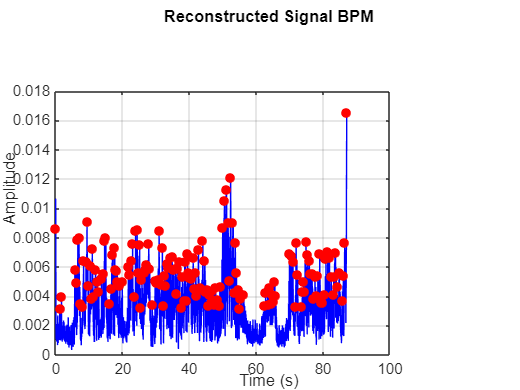

[bpm_rec, locs_rec, ibi_rec] = estimateBPM(reconstructedSignal, fsRef, 'Reconstructed Signal BPM');